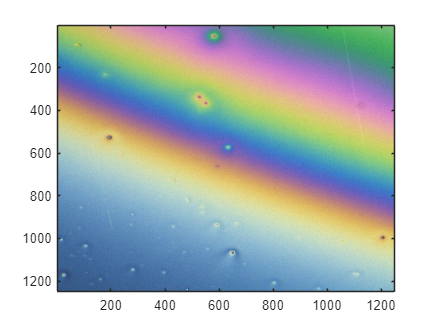

clear
clc
lim = 50;
test = imread('3.jpg');
image(test)

test = imrotate(test,-90);
load("rm_f.mat");
siz = size(test);
mat = zeros(siz(1), siz(2));
for i = 1:siz(1)
    for j = 1:siz(2)
        r = double(test(i,j,1));
        g = double(test(i,j,2));
        b = double(test(i,j,3));
        u = coordinate(mat,i,j-1);
        d = coordinate(mat,i-1,j);
        ud = coordinate(mat,i-1,j-1);
        mid = int16(nanmean([u,d,ud]));
%         if i == 1 && j == 1
%             mid = 400
%         end
        mat(i,j) = rgb2Thick(rgbmatrix,r,g,b,mid,lim);
    end
end

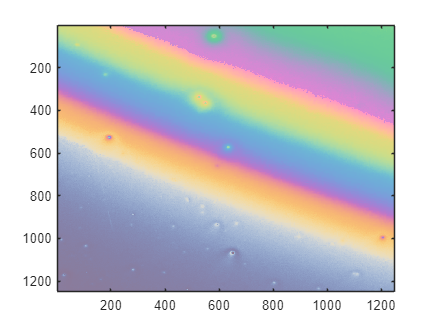

imagesc(imrotate(mat,90))
customCMap = uint8(rgbmatrix(:,min(mat,[],'all'):max(mat,[],'all'))');
colormap(customCMap);

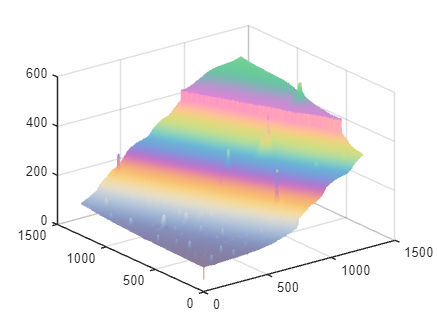

% colorbar
mesh(mat);

% colormap(pink);
% colorbar
% colorbar
% h = fspecial("gaussian");
% ma = filter2(h,mat);
% mesh(ma)

function [thick] = rgb2Thick(rgbmatrix,y1,y2,y3,mid,lim)
    if isnan(mid)
        mid = 0;
    end
    start = max(1, mid - lim);
    endp = min(mid + lim, size(rgbmatrix,2));
    delta = (rgbmatrix(1,start)-y1)^2+(rgbmatrix(2,start)-y2)^2+(rgbmatrix(3,start)-y3)^2;
    res = 0;
    for i = start+1:endp
        delta0 = (rgbmatrix(1,i)-y1)^2+(rgbmatrix(2,i)-y2)^2+(rgbmatrix(3,i)-y3)^2;
        if delta0 < delta
            delta = delta0;
            res = i;
        end
    end
    thick = res;
    if thick == 0
        thick = mid;
    end
end
function [co] = coordinate(matrix, row, col)
    siz = size(matrix);
    if row>0 && row <= siz(1) && col>0 && col <= siz(2)
        co = matrix(row,col);
    else
        co = NaN;
    end
end